clear

% Q1: Why N_RE = 12(S - S_DMRS)?
%     Because DMRS is a reference signal, its frequency expression is
%     fixed. We don't need to do the BPSK for it. We don't need to
%     calculate the REs it used.
%     Why  E = 144 for p/2-BPSK and E=288 for QPSK?
%     Because the modulation scheme determines how many bits can be carried by each RE.
%     For π/2-BPSK: Each RE carries 1 bit. For QPSK: Each RE carries 2 bits.
%     So E is twice longer in QPSK than BPSK
% Q2: pi/2-BPSK is a way to restrict the changing signal to a constant radius circle, 
%     which reduce some possible change from 1 to 0 and to -1, bringing
%     high PAPR.
%     The DFT precoding is a more efficient may to reduce the PAPR. It makes the high 
%     peak time-domain signal more 'random'. In traditional OFDM, the time-domain signal
%     is the sum of multiple independent subcarriers, which can lead to high peaks.
%     In SC-FDMA with DFT-precoding, the signal is first spread across all subcarriers
%     in the frequency domain, which reduces the likelihood of constructive interference 
%     and high peaks in the time domain.
% Q3: I compute the PAPR and show the results for all possible C at the end. 
% Q4: Here I implement it in a matrix form.
% Q5: Here if the DMRS has a good traits like PSS that |PSS|.^2 = ones,
%     that it can be used for channel estimation.
% Q6: Frequency hopping sometimes will avoid some bad condition bandwidth, then
%     the DMRS would estimate the channel in the 'hopped' bandwidth, which
%     gives an estimation for a part of the channel. Not all information.


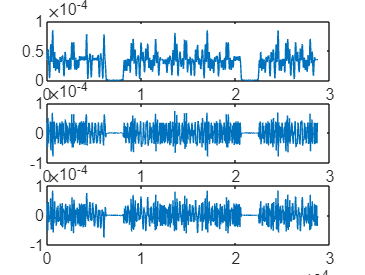

%M=[0xFFFFFFFF, 0x4BA5A933, 0x7D910E5A, 0x6D26339C, 0x71C7C3E0,0x7E0FFC00, 0x731D8E64, 0x6B44F5B0, 0x7DC218EC, 0x4DA1B746, 0x42F0FFFF]''
M = [4294967295,   1269147955,   2106658394,   1831220124,   1908917216,   2114976768,   1931316836, 1799681456,   2109872364,   1302443846,   1123090431];

% K=11 bit, S=14 symbols
C11_3gpp=zeros(2048,14*12);
C11_3gpp_normal=zeros(2048,14*12);
C11_3gpp_QPSK = zeros(2048,14*12);
cw_QPSK = zeros(16,1);
cw = zeros(32,1);
cw_normal = zeros(32,1);
DMRS = ones(1,12);
%DMRS = zeros(1,12);
% C is the all possible 11 bits input sequence.
% We are generating a big table for every possible coding result
for C=0:2047 % C is in the input c-sequence, C=[c0 c1 c2 ... c(K-1)]
%  a
  D=mod(C,2)*M(1); % D is the d-sequence, D=[d0 d1 d2 ... d31];
  for n=2:11
    D = bitxor(D,(mod(floor(C*(2^(1-n))),2)*M(n)));% D become the 32bits sequence
  end
  i = 0;
  for n=0:2:31 % This is pi/2-BPSK
    i = i+1;
    bit0=(1-(2*mod(floor(D/(2^n)),2)));
    bit1=(1-(2*mod(floor(D/(2^(n+1))),2)));
    cw_normal(1+n) = bit0;
    cw_normal(2+n) = bit1;
    cw(1+n) = bit0;
    cw(2+n) = sqrt(-1)*bit1; % to use normal BPSK, remove the pi/2 rotation
    cw_QPSK(1+(n/2)) = (bit0 + sqrt(-1)*bit1)/sqrt(2);
  end
  idx=0;
  for symb=0:13
    for re=0:11
      if (symb==3 || symb==10)
         C11_3gpp(1+C,1+(symb*12)+(0:11)) = DMRS; % This should be the DMRS 
         C11_3gpp_normal(1+C,1+(symb*12)+(0:11)) = DMRS;
         C11_3gpp_QPSK(1+C,1+(symb*12)+(0:11)) = DMRS; 
         symb=symb+1;
      end
%      fprintf("symb %d,re %d\n",symb,re);
      C11_3gpp(1+C,1+(symb*12)+re) = cw(1+rem(idx,32)); % rate-matching of the cw-sequence
      C11_3gpp_normal(1+C,1+(symb*12)+re) = cw_normal(1+rem(idx,32));
      C11_3gpp_QPSK(1+C,1+(symb*12)+re) = cw_QPSK(1+rem(idx,16)); % rate-matching of the cw-sequence
      idx=idx+1;
    end
  end
end

% C is the code sequence to be generated
C=190;
c0_t=[];
c0_t_normal=[];
c0_t_QPSK=[];
hopping = 0;%2048-12;
zero_zone = zeros(1,hopping);
for symb=0:13
% extract OFDM symbols "symb" from coded sequence and do the DFT-precoding (SC-FDMA in the lecture slides)
  if (symb==3) || (symb==10)
    %direct insert
    c0_f = C11_3gpp(1+C,1+(symb*12) + (0:11));
    c0_f_normal = C11_3gpp_normal(1+C,1+(symb*12) + (0:11));
    c0_f_QPSK = C11_3gpp_QPSK(1+C,1+(symb*12) + (0:11));
  else
    % DFT precoding
    c0_f = fft(C11_3gpp(1+C,1+(symb*12) + (0:11)));
    c0_f_normal = fft(C11_3gpp_normal(1+C,1+(symb*12) + (0:11)));
    c0_f_QPSK = fft(C11_3gpp_QPSK(1+C,1+(symb*12) + (0:11)));
  end

    %OFDM modulation
  if symb<7
      c0_f_fhop = [c0_f, zero_zone];
      c0_f_normal_fhop = [c0_f_normal, zero_zone];
      c0_f_QPSK_fhop = [c0_f_QPSK, zero_zone];
  end
  if symb>=7
      c0_f_fhop = [zero_zone c0_f];
      c0_f_normal_fhop = [zero_zone c0_f_normal];
      c0_f_QPSK_fhop = [zero_zone c0_f_QPSK];
  end
  c0_t = [c0_t ifft(c0_f_fhop,2048)];
  c0_t_normal = [c0_t_normal ifft(c0_f_normal_fhop,2048)];
  c0_t_QPSK = [c0_t_QPSK ifft(c0_f_QPSK_fhop,2048)];
end

figure
subplot(311)
plot(abs(c0_t.^2));
subplot(312)
plot(real(c0_t.^2));
subplot(313)
plot(imag(c0_t.^2));

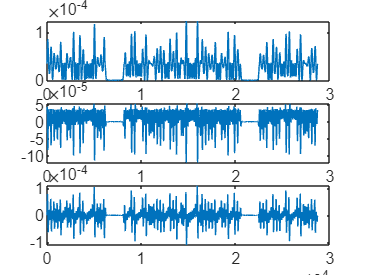


figure
subplot(311)
plot(abs(c0_t_normal.^2));
subplot(312)
plot(real(c0_t_normal.^2));
subplot(313)
plot(imag(c0_t_normal.^2));

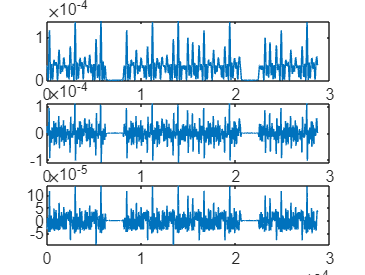


figure
subplot(311)
plot(abs(c0_t_QPSK.^2));
subplot(312)
plot(real(c0_t_QPSK.^2));
subplot(313)
plot(imag(c0_t_QPSK.^2));

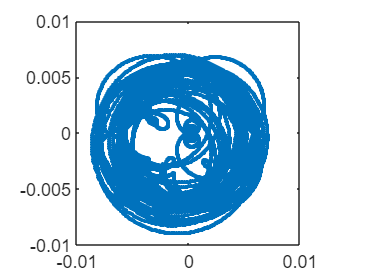


figure
plot(real(c0_t),imag(c0_t),'.')
axis('square') 

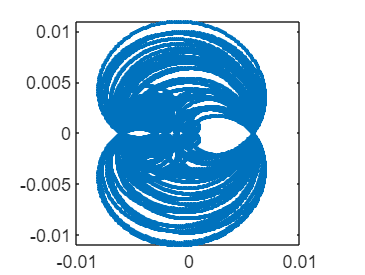

figure
plot(real(c0_t_normal),imag(c0_t_normal),'.')
axis('square') 

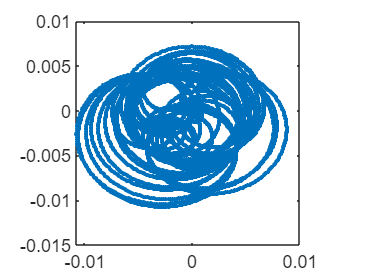

figure
plot(real(c0_t_QPSK),imag(c0_t_QPSK),'.')
axis('square')


%show PAPR
disp(max(abs(c0_t).^2)/mean(abs(c0_t).^2))

    2.8338


disp(max(abs(c0_t_normal).^2)/mean(abs(c0_t_normal).^2))

    4.1380


disp(max(abs(c0_t_QPSK).^2)/mean(abs(c0_t_QPSK).^2))

    4.6195


% possible channel
N = length(c0_t);
noise = randn(1,N);
A = 0.3;
c0_t_n = c0_t + A*noise;

% data detecting and decoding
% to simplify, we ignore the prefix
rx = c0_t_QPSK;
C11_3gpp_table = C11_3gpp_QPSK;
% using ML method, using C11_3gpp to detect
Symb = zeros(14,2048);
Symb_f = zeros(14,2048);
Symb_F = [];
Start = 1;
End = 2048;
for i=0:13
    Symb(i+1,:) = rx(Start:End);
    Symb_f = fft(Symb(i+1,:),2048);
    Symb_ff = Symb_f(1:12);
    if i~=3 && i~=10
        Symb_ff = ifft(Symb_ff);
    end
    Symb_F = [Symb_F Symb_ff];
    Start = Start+2048;
    End = End + 2048;
end
Symb_FF = repmat(Symb_F,2048,1);

ML_detc = sum((conj(C11_3gpp_table).*Symb_FF),2).^2;
[~, bits_dec] = max(abs(ML_detc));
bits_dec = bits_dec - 1

bits_dec = 190

bits = dec2bin(bits_dec,11)

bits = '00010111110'

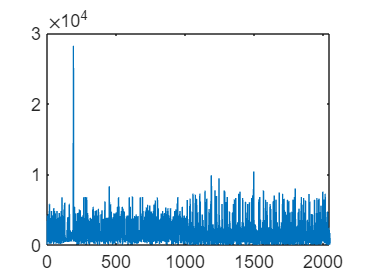

plot(abs(ML_detc))

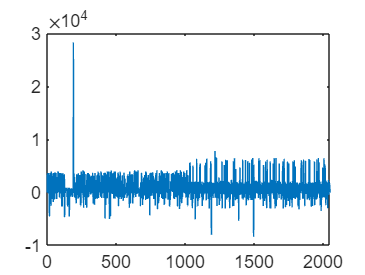

figure
plot(real(ML_detc))

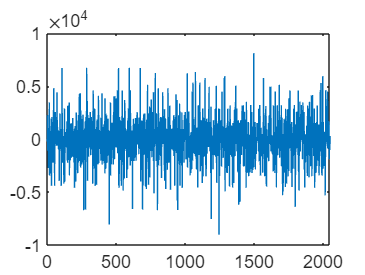

figure
plot(imag(ML_detc))

PAPR = [];
PAPR_norm = [];
PAPR_QPSK = [];

for C = 0:2047
    c0_t = [];
    c0_t_normal = [];
    c0_t_QPSK = [];
    hopping = 0; % 2048 - 12
    zero_zone = zeros(1, hopping);

    for symb = 0:13
        % Extract OFDM symbols "symb" from coded sequence and perform DFT precoding (SC-FDMA)
        if (symb == 3) || (symb == 10)
            % Direct insertion for specific symbols
            c0_f = C11_3gpp(1 + C, 1 + (symb * 12) + (0:11));
            c0_f_normal = C11_3gpp_normal(1 + C, 1 + (symb * 12) + (0:11));
            c0_f_QPSK = C11_3gpp_QPSK(1 + C, 1 + (symb * 12) + (0:11));
        else
            % Perform DFT precoding for other symbols
            c0_f = fft(C11_3gpp(1 + C, 1 + (symb * 12) + (0:11)));
            c0_f_normal = fft(C11_3gpp_normal(1 + C, 1 + (symb * 12) + (0:11)));
            c0_f_QPSK = fft(C11_3gpp_QPSK(1 + C, 1 + (symb * 12) + (0:11)));
        end

        % Perform OFDM modulation
        if symb < 7
            c0_f_fhop = [c0_f, zero_zone];
            c0_f_normal_fhop = [c0_f_normal, zero_zone];
            c0_f_QPSK_fhop = [c0_f_QPSK, zero_zone];
        else
            c0_f_fhop = [zero_zone, c0_f];
            c0_f_normal_fhop = [zero_zone, c0_f_normal];
            c0_f_QPSK_fhop = [zero_zone, c0_f_QPSK];
        end

        c0_t = [c0_t ifft(c0_f_fhop, 2048)];
        c0_t_normal = [c0_t_normal ifft(c0_f_normal_fhop, 2048)];
        c0_t_QPSK = [c0_t_QPSK ifft(c0_f_QPSK_fhop, 2048)];
    end

    % Calculate PAPR
    PAPR = [PAPR abs(max(abs(c0_t).^2) / mean(abs(c0_t).^2))];
    PAPR_norm = [PAPR_norm abs(max(abs(c0_t_normal).^2) / mean(abs(c0_t_normal).^2))];
    PAPR_QPSK = [PAPR_QPSK abs(max(abs(c0_t_QPSK).^2) / mean(abs(c0_t_QPSK).^2))];
end

% Define x-axis and plot PAPR results
xc = 0:2047;
figure;
plot(xc, 10*log10(PAPR), 'r', 'DisplayName', '3GPP pi/2-BPSK');
hold on;
plot(xc, 10*log10(PAPR_norm), 'g', 'DisplayName', '3GPP BPSK');
plot(xc, 10*log10(PAPR_QPSK), 'b', 'DisplayName', '3GPP pi/2-QPSK');
hold off;

% Add labels and legend
xlabel('Codeword Index (C)');
ylabel('PAPR (dB)');
title('PAPR Comparison');
legend('show');
grid on;

% 
% % another method, not doing this
% 
% Symb = zeros(14,2048);
% Symb_f = zeros(14,2048);
% Start = 1;
% End = 2048;
% for i=0:13
%     disp(["Symbol:"+num2str(i)])
%     Symb(i+1,:) = rx(Start:End);
%     Symb_f = fft(Symb(i+1,:),2048);
%     Symb_ff = Symb_f(1:12);
%     if i~=3 && i~=10
%         Symb_ff = ifft(Symb_ff);
%     end
%     figure
%     plot(abs(Symb_ff))
%     axis('square')
%     figure
%     plot(real(Symb_ff), imag(Symb_ff))
%     axis('square')
%     Start = Start+2048;
%     End = End + 2048;
% end

% % Frequency Grid Visualization
% % Verify matrix size
% disp(size(C11_3gpp)); % Should output [2048, 168]
% disp(size(C11_3gpp_QPSK)); % Should output [2048, 168]
% 
% % Generate X (time), Y (frequency), Z (magnitude)
% [time_samples, freq_symbols] = size(C11_3gpp);
% [X, Y] = meshgrid(1:time_samples, 1:freq_symbols);
% 
% % Plot 3GPP Matrix in 3D
% figure;
% surf(X, Y, imag(C11_3gpp'));
% title('3GPP Frequency-Time Grid');
% xlabel('Time Samples');
% ylabel('Frequency Subcarriers');
% zlabel('Magnitude');
% colormap jet;
% colorbar;
% shading interp;
% 
% % Plot 3GPP_QPSK Matrix in 3D
% figure;
% surf(X, Y, imag(C11_3gpp_QPSK'));
% title('3GPP QPSK Frequency-Time Grid');
% xlabel('Time Samples');
% ylabel('Frequency Subcarriers');
% zlabel('Magnitude');
% colormap jet;
% colorbar;
% shading interp;
